
8793

ans = 8793

IAE = 0.82635				P = 100.9215		I = 21.9031		D = 3.6106
IAE = 0.25424				P = 68.9626		I = 86.7012		D = 1.855
IAE = 0.21357				P = 94.9597		I = 115.5193		D = 2.1435
IAE = 2.1607				P = 94.7103		I = 45.1192		D = 15.1444
IAE = 2.149				P = 56.9892		I = 12.9103		D = 7.8789
IAE = 1.1037				P = 108.8674		I = 101.525		D = 11.9714
IAE = 0.79584				P = 63.351		I = 60.0125		D = 4.975
IAE = 0.81009				P = 121.3693		I = 88.0109		D = 0.12328
IAE = 0.95802				P = 102.1371		I = 87.4657		D = 9.8499
IAE = 1.5416				P = 17.1164		I = 54.0016		D = 5.7212
IAE = 1.6772				P = 30.5108		I = 84.4299		D = 10.3813
IAE = 6.6352				P = 16.4358		I = 81.1153		D = 13.5356
IAE = 0.30353				P = 68.414		I = 67.2662		D = 1.6217
IAE = 11.5695				P = 7.3515		I = 24.5649		D = 9.4128
IAE = 1.3411				P = 60.0307		I = 65.5728		D = 9.3181
IAE = 0.8708				P = 125.7858		I = 95.8114		D = 8.3489
IAE = 1.094				P = 87.3561		I = 53.7959		D = 7.2736
IAE = 1.5167				P = 111.4882		I = 94.4236		D = 15.4672
IAE = 0.25004				P = 63.5653		I 

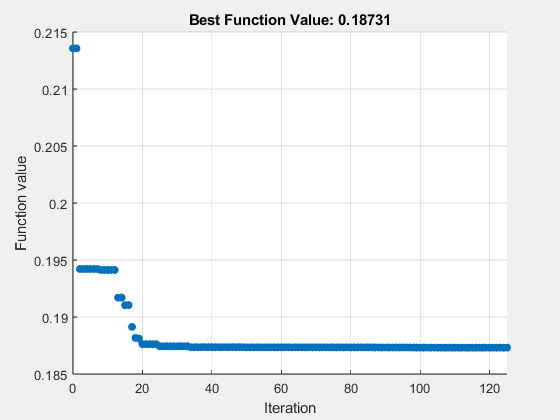

% Set nondefault solver options
options = optimoptions("particleswarm","InertiaRange",Inertia_range,...
    "SelfAdjustmentWeight",2.8,"SocialAdjustmentWeight",1.3,"MaxIterations",...
    600,"Display","iter","PlotFcn","pswplotbestf");

% Solve
[sol,obj] = particleswarm(@tunning,numvar,lower_bounds,...
    upper_bounds,options);


% Clear variables
clearvars options